依赖[统一实验分析作图v19.1.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases/)

模板细胞的纯cue、偶联和迁移5组

MOpBaseline=TransferLearning.MOpBaseline;

GroupNtats=UniExp.NtatsCellStrip(MOpBaseline.QueryNTATS(UniExp.ReadQueryTable(TransferLearning.ProjectPath("查询表.xlsx"),'Fig1J'),UniExp.Flags.ZScore,1:24,UniExp.Flags.Median)).NTATS;

Sample=GroupNtats(:,:,["naive_AudioWater","learned_AudioWater","transfer_LightWater"]);
Baseline=max(Sample(:,1:24,:),[],2);
Response=max(Sample(:,25:32,:),[],2);
LearnedResponse=Response.learned_AudioWater;
TransferResponse=Response.transfer_LightWater;

Logical=TransferResponse>Baseline.transfer_LightWater&TransferResponse>Response.naive_AudioWater&LearnedResponse>TransferResponse&LearnedResponse>Baseline.learned_AudioWater;
GroupNtats=GroupNtats(Logical,:,:);
[~,SortIndex]=sort(LearnedResponse(Logical),'descend');

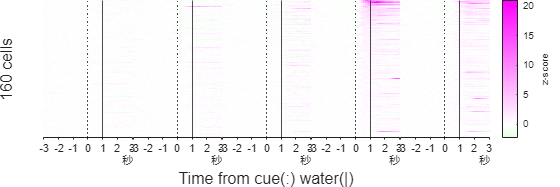

Fig=figure;
Layout=tiledlayout(1,5,TileSpacing='none',Padding='tight');
[~,Axes]=UniExp.LanearHeatmap(GroupNtats{SortIndex,:,["naive_AudioOnly","naive_LightOnly","naive_AudioWater","learned_AudioWater","transfer_LightWater"]},XData=seconds([-3,3]),Layout=Layout,Flags=[UniExp.Flags.HideYAxis,UniExp.Flags.SymmetricColormap],LMHColor=[0,1,0;1,1,1;1,0,1]);
for A=1:5
	xline(Axes(A),seconds(0),':k');
	xline(Axes(A),seconds(1),'-k');
end
ylabel(Layout,sprintf('%u cells',height(GroupNtats)));
xlabel(Layout,'Time from cue(:) water(|)');
CB=colorbar;
CB.Label.String='z-score';
MATLAB.Graphics.FigureAspectRatio(3,1,MATLAB.Flags.Narrow);
print(Fig,TransferLearning.ProjectPath('Fig1J.svg'),'-dsvg');